BL.AI.U4AID25064

Sudarshan Rao

Lab Exercise - 4

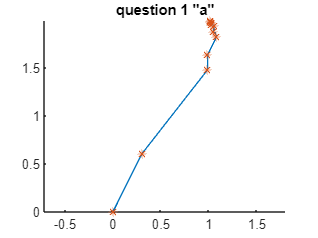

% question - 1
% a

clear;
clf;
clc;

A = [2,1,-1;1,2,-1;-1,-1,4];
b = [1;2;9];
x0 = [0;0;0];
xa = x0;

for i = 1:10
    g = A*x0-b;
    alpha = g'*g/(g'*A*g);
    xn = x0 - alpha*g;
    xa = [xa xn];
    x0 = xn;
    errnorm = norm(A*xn-b,2);
    if errnorm < 0.001
        break;
    end
end
hold on
plot(xa(1,:),xa(2,:));
hold on
plot(xa(1,:),xa(2,:),'*');
axis equal
title('question 1 "a"')

xa

xa =          0    0.3028    0.9872    0.9875    1.0853    1.0515    1.0576    1.0311    1.0283    1.0146    1.0128
         0    0.6056    1.4798    1.6356    1.8319    1.8810    1.9388    1.9541    1.9754    1.9805    1.9894
         0    2.7254    2.4551    2.9600    2.8993    3.0039    2.9787    3.0074    2.9935    3.0041    2.9974


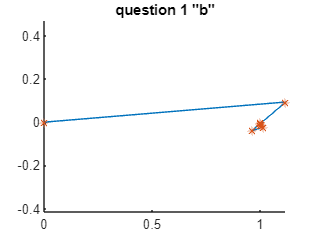

% question - 1
% b

clear;
clf;
clc;

A = [11,2,1;2,4,-1;1,-1,6];
b = [12;1;7];
x0 = [0;0;0];
xa = x0;
for i = 1:10
    g = A*x0-b;
    alpha = g'*g/(g'*A*g);
    xn = x0 - alpha*g;
    xa = [xa xn];
    x0 = xn;
    errnorm = norm(A*xn-b,2);
    if errnorm < 0.001
        break;
    end
end
hold on
plot(xa(1,:),xa(2,:));
hold on
plot(xa(1,:),xa(2,:),'*');
axis equal
title('question 1 "b"')

xa

xa =          0    1.1171    0.9620    1.0153    0.9992    1.0051    0.9998    1.0018    0.9999    1.0006    1.0000
         0    0.0931   -0.0385   -0.0226   -0.0171   -0.0094   -0.0057   -0.0032   -0.0019   -0.0011   -0.0007
         0    0.6516    0.9363    0.9727    0.9938    0.9963    0.9975    0.9987    0.9992    0.9995    0.9997


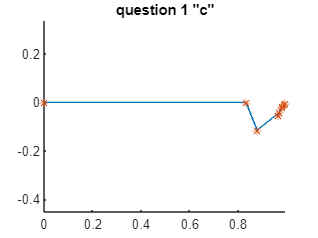

% question - 1
% c

clear;
clf;
clc;

A = [3,0,1;0,4,2;1,2,3];
b = [3;0;1];
x0 = [0;0;0];
xa = x0;
for i = 1:10
    g = A*x0-b;
    alpha = g'*g/(g'*A*g);
    xn = x0 - alpha*g;
    xa = [xa xn];
    x0 = xn;
    errnorm = norm(A*xn-b,2);
    if errnorm < 0.001
        break;
    end
end
hold on
plot(xa(1,:),xa(2,:));
hold on
plot(xa(1,:),xa(2,:),'*');
axis equal
title('question 1 "c"')

xa

xa =          0    0.8333    0.8790    0.9720    0.9658    0.9830    0.9842    0.9930    0.9933    0.9970    0.9971
         0         0   -0.1143   -0.0407   -0.0543   -0.0153   -0.0226   -0.0067   -0.0097   -0.0028   -0.0041
         0    0.2778    0.1406    0.1103    0.0582    0.0459    0.0245    0.0197    0.0105    0.0084    0.0045


% question - 2
% a
clear;
clc;
clf;

syms x y;
f = 4*x^2 + 3*y^2 - 16*x - 36*y + 25;

a = diff(f,x);
b = diff(f,y);

sol = solve([a == 0, b == 0], [x, y]);
optx = sol.x;
opty = sol.y;

H = hessian(f,[x y]);

minf = subs(f, [x y], [optx, opty]);

fprintf('f(x,y) = %.4f\n', double(minf));

f(x,y) = -99.0000


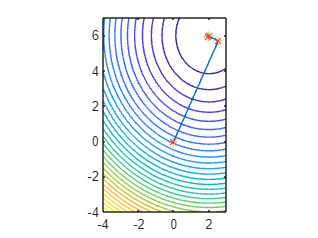

% question - 2
% b
clear;
clf;
clc;

X1=-4:.25:3;
X2=-4:.25:7;
[x,y] = meshgrid(X1,X2);

f = 4*x.^2 + 3*y.^2 - 16*x - 36*y + 25;

contour(x,y,f,30);
x0 = [0;0];
A = [8,0;0,6];
b = [16;36];
xa = x0;

for i=1:10
    g=A*x0-b;
    alpha=g'*g/(g'*A*g);
    xn=x0-alpha*g;
    xa=[xa xn];
    x0=xn;
    errnorm=norm(A*xn-b,2);
    if errnorm <0.001
        break;
    end
end  

hold on
plot(xa(1,:) , xa(2,:))
hold on
plot(xa(1,:), xa(2,:),'*')
axis equal

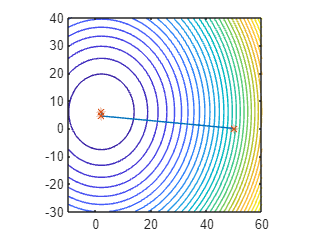

% question - 2
% c

clear;
clf;
clc;

X1 = -10:1:60;
X2 = -30:1:40;
[x,y] = meshgrid(X1,X2);

f = 4*x.^2 + 3*y.^2 - 16*x - 36*y + 25;

contour(x,y,f,30);
hold on;

x0 = [50;0];
A = [8,0;0,6];
b = [16;36];
xa = x0;

for i=1:10
    g=A*x0-b;
    alpha=g'*g/(g'*A*g);
    xn=x0-alpha*g;
    xa=[xa xn];
    x0=xn;
    errnorm=norm(A*xn-b,2);
    if errnorm <0.001
        break;
    end
end  


plot(xa(1,:) , xa(2,:))
hold on
plot(xa(1,:), xa(2,:),'*')
axis equal

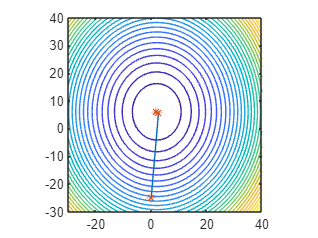

% question - 2
% d
clear;
clf;
clc;

X1 = -30:1:40;
X2 = -30:1:40;
[x,y] = meshgrid(X1,X2);

f = 4*x.^2 + 3*y.^2 - 16*x - 36*y + 25;

contour(x,y,f,30);
hold on;

x0 = [0;-25];
A = [8,0;0,6];
b = [16;36];
xa = x0;

for i=1:10
    g=A*x0-b;
    alpha=g'*g/(g'*A*g);
    xn=x0-alpha*g;
    xa=[xa xn];
    x0=xn;
    errnorm=norm(A*xn-b,2);
    if errnorm <0.001
        break;
    end
end  

plot(xa(1,:) , xa(2,:))
hold on
plot(xa(1,:), xa(2,:),'*')
axis equal

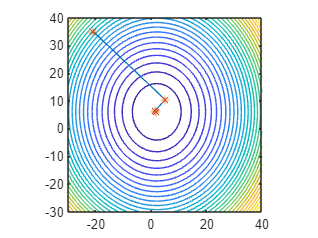

% question - 2
% e
clear;
clf;
clc;

X1 = -30:1:40;
X2 = -30:1:40;
[x,y] = meshgrid(X1,X2);

f = 4*x.^2 + 3*y.^2 - 16*x - 36*y + 25;

contour(x,y,f,30);
hold on;

x0 = [-21;35];
A = [8,0;0,6];
b = [16;36];
xa = x0;

for i=1:10
    g=A*x0-b;
    alpha=g'*g/(g'*A*g);
    xn=x0-alpha*g;
    xa=[xa xn];
    x0=xn;
    errnorm=norm(A*xn-b,2);
    if errnorm <0.001
        break;
    end
end  

plot(xa(1,:) , xa(2,:))
hold on
plot(xa(1,:), xa(2,:),'*')
axis equal

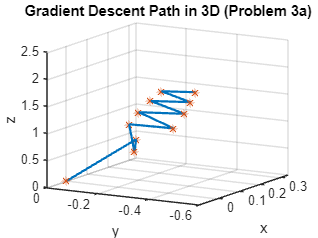

% question - 3
% a
clear;
clf;
clc;

X1 = -30:1:40;
X2 = -30:1:40;
X3 = -30:1:40;
[x, y, z] = meshgrid(X1, X2, X3);

f = 6*x.^2 + 8*y.^2 + z.^2 + 2*x.*z - 4*y.*z - 3*x - 3*z;

x0 = [0; 0; 0];
A = [12, 0, 2; 0, 16, 4; 2, 4, 2];
b = [3; 0; 3];
xa = x0;

for i = 1:10
    g = A * x0 - b;
    alpha = (g' * g) / (g' * A * g);
    xn = x0 - alpha * g;
    xa = [xa, xn];
    x0 = xn;
    errnorm = norm(A * xn - b, 2);
    if errnorm < 0.001
        break;
    end
end  



plot3(xa(1,:), xa(2,:), xa(3,:), '-', 'LineWidth', 1.5);
hold on;
plot3(xa(1,:), xa(2,:), xa(3,:), '*', 'MarkerSize', 6, 'MarkerFaceColor', 'r');
grid on;
title('Gradient Descent Path in 3D (Problem 3a)');
xlabel('x');
ylabel('y');
zlabel('z');

view([-59.69 14.42])

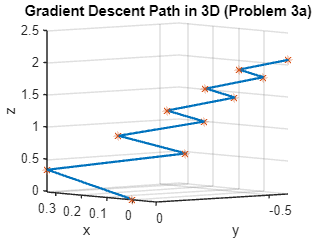

% question - 3 
% b
clear;
clf;
clc;

X1 = -30:1:40;
X2 = -30:1:40;
X3 = -30:1:40;
[x, y, z] = meshgrid(X1, X2, X3);

f = 9*x.^2 + 5*y.^2 + 3*z.^2 -36*x + 30*y -8*z;

x0 = [0; 0; 0];
A = [12, 0, 2; 0, 16, 4; 2, 4, 2];
b = [3; 0; 3];
xa = x0;

for i = 1:10
    g = A * x0 - b;
    alpha = (g' * g) / (g' * A * g);
    xn = x0 - alpha * g;
    xa = [xa, xn];
    x0 = xn;
    errnorm = norm(A * xn - b, 2);
    if errnorm < 0.001
        break;
    end
end  



plot3(xa(1,:), xa(2,:), xa(3,:), '-', 'LineWidth', 1.5);
hold on;
plot3(xa(1,:), xa(2,:), xa(3,:), '*', 'MarkerSize', 6, 'MarkerFaceColor', 'r');
grid on;
title('Gradient Descent Path in 3D (Problem 3a)');
xlabel('x');
ylabel('y');
zlabel('z');
view([-129.44 4.84])

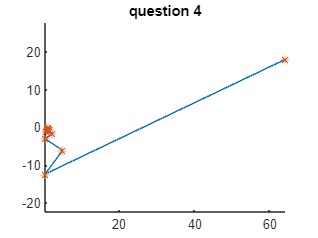

% question - 4

clear;
clf;
clc;

A = [9,1,1,0,0;1,5,0,0,2;1,0,3,0,0;0,0,0,4,2;0,2,0,2,6];
b = [10;3;4;2;6];
x0 = [64;18;1;18;64];
xa = x0;

for i = 1:10
    g = A*x0-b;
    alpha = g'*g/(g'*A*g);
    xn = x0 - alpha*g;
    xa = [xa xn];
    x0 = xn;
    errnorm = norm(A*xn-b,2);
    if errnorm < 0.001
        break;
    end
end
hold on
plot(xa(1,:),xa(2,:));
hold on
plot(xa(1,:),xa(2,:),'*');
axis equal
title('question 4')

xa

xa =    64.0000    0.2767    4.9332    0.3316    2.3406    0.7226    1.4777    0.8958    1.1759    0.9599    1.0661
   18.0000  -12.3911   -6.1168   -3.0560   -1.6381   -1.1607   -0.5641   -0.4563   -0.2101   -0.1775   -0.0801
    1.0000   -5.8625   -2.0108   -1.1176    0.1431    0.3510    0.7411    0.7911    0.9188    0.9301    0.9737
   18.0000   -3.5679   -6.0427   -3.4163   -2.4084   -1.4604   -0.9058   -0.5837   -0.3464   -0.2283   -0.1334
   64.0000   14.9821    5.5882    5.0259    3.0130    2.3393    1.8494    1.4884    1.3398    1.1850    1.1329


% question - 5

clear;
clf;
clc;

rng(42); 
Temp = randi([1, 10], 5, 5);
A = Temp + Temp';      
A = A + 10 * eye(5);   

x_true = [1; 2; 3; 4; 5];
b = A * x_true;

x0 = zeros(5, 1); 
xa = x0;

max_iter = 1000;
iter_count = 0;

for i = 1:max_iter
    g = A * x0 - b;
    alpha = (g' * g) / (g' * A * g);
    xn = x0 - alpha * g;
    xa = [xa xn];
    x0 = xn;
    
    iter_count = iter_count + 1;
    errnorm = norm(A * xn - b, 2);
    
    if errnorm < 0.0001
        break;
    end
end

disp(['Solution converged in ', num2str(iter_count), ' iterations.']);

Solution converged in 1000 iterations.


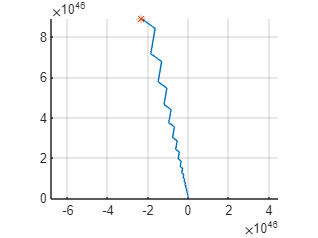


hold on;
plot(xa(1,:), xa(2,:));
plot(xa(1,end), xa(2,end),'*');

grid on;
axis equal;
hold off;